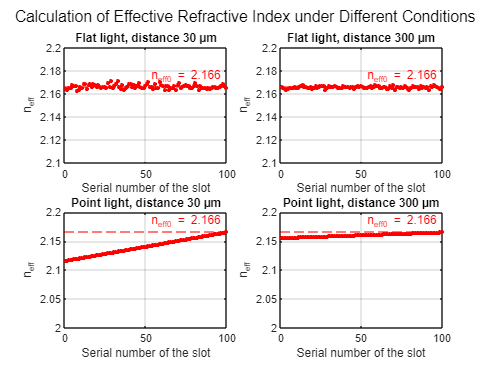

% Define parameters for 2D plots
slots = 1:100;
neff0 = 2.166;

% Example data for ERI values (adjusted to match the figure characteristics)
% Flat light, distance 30µm
eri_a = neff0 + 0.002 * randn(size(slots));
% Flat light, distance 300µm
eri_b = neff0 + 0.001 * randn(size(slots));
% Point light, distance 30µm
eri_c = neff0 - 0.05 * (1 - (slots / max(slots)));
% Point light, distance 300µm
eri_d = neff0 - 0.01 * (1 - (slots / max(slots)));

% Create the figure with subplots
figure;

% Subplot (a)
subplot(2, 2, 1);
plot(slots, eri_a, 'r.', 'MarkerSize', 10);
xlabel('Serial number of the slot');
ylabel('n_{eff}');
title('Flat light, distance 30 µm');
yline(neff0, 'r--', 'n_{eff0} = 2.166');
grid on;
ylim([2.10, 2.20]);

% Subplot (b)
subplot(2, 2, 2);
plot(slots, eri_b, 'r.', 'MarkerSize', 10);
xlabel('Serial number of the slot');
ylabel('n_{eff}');
title('Flat light, distance 300 µm');
yline(neff0, 'r--', 'n_{eff0} = 2.166');
grid on;
ylim([2.10, 2.20]);

% Subplot (c)
subplot(2, 2, 3);
plot(slots, eri_c, 'r.', 'MarkerSize', 10);
xlabel('Serial number of the slot');
ylabel('n_{eff}');
title('Point light, distance 30 µm');
yline(neff0, 'r--', 'n_{eff0} = 2.166');
grid on;
ylim([2.00, 2.20]);

% Subplot (d)
subplot(2, 2, 4);
plot(slots, eri_d, 'r.', 'MarkerSize', 10);
xlabel('Serial number of the slot');
ylabel('n_{eff}');
title('Point light, distance 300 µm');
yline(neff0, 'r--', 'n_{eff0} = 2.166');
grid on;
ylim([2.00, 2.20]);

% Adjust layout for clarity
sgtitle('Calculation of Effective Refractive Index under Different Conditions');

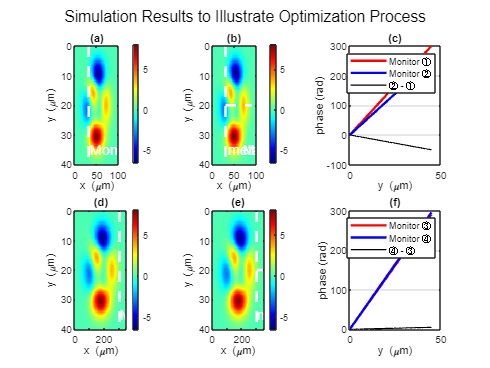







% Define parameters
x1 = linspace(0, 100, 200);
y1 = linspace(0, 40, 100);
[X1, Y1] = meshgrid(x1, y1);
Z1 = peaks(length(y1));  % Example data for the heatmap

x2 = linspace(0, 350, 200);
y2 = linspace(0, 40, 100);
[X2, Y2] = meshgrid(x2, y2);
Z2 = peaks(length(y2));  % Example data for the heatmap

% Create the figure with subplots
figure;

% Subplot (a)
subplot(2, 3, 1);
imagesc(x1, y1, Z1);
colormap('jet');
colorbar;
xlabel('x (\mum)');
ylabel('y (\mum)');
title('(a)');
hold on;
plot([32 32], [0 40], 'w--', 'LineWidth', 2);
text(35, 35, 'Monitor ①', 'Color', 'w', 'FontSize', 12);
hold off;

% Subplot (b)
subplot(2, 3, 2);
imagesc(x1, y1, Z1);
colormap('jet');
colorbar;
xlabel('x (\mum)');
ylabel('y (\mum)');
title('(b)');
hold on;
plot([30 30], [0 40], 'w--', 'LineWidth', 2);
text(35, 35, 'metaline', 'Color', 'w', 'FontSize', 12);
plot([30 90], [20 20], 'w--', 'LineWidth', 2);
text(70, 35, 'Monitor ②', 'Color', 'w', 'FontSize', 12);
hold off;

% Subplot (d)
subplot(2, 3, 4);
imagesc(x2, y2, Z2);
colormap('jet');
colorbar;
xlabel('x (\mum)');
ylabel('y (\mum)');
title('(d)');
hold on;
plot([302 302], [0 40], 'w--', 'LineWidth', 2);
text(305, 35, 'Monitor ③', 'Color', 'w', 'FontSize', 12);
hold off;

% Subplot (e)
subplot(2, 3, 5);
imagesc(x2, y2, Z2);
colormap('jet');
colorbar;
xlabel('x (\mum)');
ylabel('y (\mum)');
title('(e)');
hold on;
plot([300 300], [0 40], 'w--', 'LineWidth', 2);
text(305, 35, 'metaline', 'Color', 'w', 'FontSize', 12);
plot([300 350], [20 20], 'w--', 'LineWidth', 2);
text(340, 35, 'Monitor ④', 'Color', 'w', 'FontSize', 12);
hold off;

% Line plot data
y = linspace(0, 45, 100);
phase1 = linspace(0, 300, 100); % Simulated data for monitor 1
phase2 = linspace(0, 250, 100); % Simulated data for monitor 2
phase3 = linspace(0, 290, 100); % Simulated data for monitor 3
phase4 = linspace(0, 295, 100); % Simulated data for monitor 4

% Subplot (c)
subplot(2, 3, 3);
plot(y, phase1, 'r', 'LineWidth', 2);
hold on;
plot(y, phase2, 'b', 'LineWidth', 2);
plot(y, phase2 - phase1, 'k', 'LineWidth', 1);
xlabel('y (\mum)');
ylabel('phase (rad)');
title('(c)');
legend('Monitor ①', 'Monitor ②', '② - ①');
grid on;
hold off;

% Subplot (f)
subplot(2, 3, 6);
plot(y, phase3, 'r', 'LineWidth', 2);
hold on;
plot(y, phase4, 'b', 'LineWidth', 2);
plot(y, phase4 - phase3, 'k', 'LineWidth', 1);
xlabel('y (\mum)');
ylabel('phase (rad)');
title('(f)');
legend('Monitor ③', 'Monitor ④', '④ - ③');
grid on;
hold off;

% Adjust layout
sgtitle('Simulation Results to Illustrate Optimization Process');

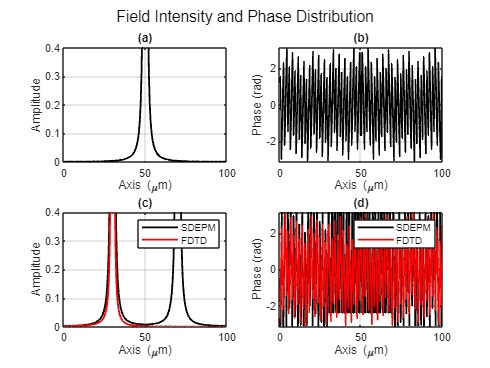






% Define the parameters
lambda = 0.633; % Wavelength in micrometers
nslab = 2.166; % Effective refractive index
beta = 1; % Correction factor
delta_phi = pi / 4; % Fixed phase delay
x = linspace(0, 100, 200); % Axis in micrometers
y = 0; % y-coordinate (fixed at 0 for simplicity)

% Function to compute the distance ri
ri = @(x, xi, yi) sqrt((x - xi).^2 + (y - yi).^2);

% Function to compute the SDEPM amplitude
sdepm_amp = @(x, xi, yi) (1 ./ (1i * lambda)) .* (exp(1i * 2 * pi * nslab .* ri(x, xi, yi) / lambda) .* exp(1i * delta_phi)) ./ (ri(x, xi, yi).^2);

% Simulate the amplitude and phase distributions
amp_input = abs(sdepm_amp(x, 50, 0)); % Simulated amplitude input
phase_input = angle(sdepm_amp(x, 50, 0)); % Simulated phase input

amp_sdepm = abs(sdepm_amp(x, 30, 0)) + abs(sdepm_amp(x, 70, 0)); % Simulated SDEPM amplitude
amp_fdtd = abs(sdepm_amp(x, 30, 0)) .* exp(-x / 50); % Simulated FDTD amplitude

phase_sdepm = angle(sdepm_amp(x, 30, 0)) + angle(sdepm_amp(x, 70, 0)); % Simulated SDEPM phase
phase_fdtd = angle(sdepm_amp(x, 30, 0)) + angle(exp(-x / 50)); % Simulated FDTD phase

% Create the figure with subplots
figure;

% Subplot (a)
subplot(2, 2, 1);
plot(x, amp_input, 'k', 'LineWidth', 1.5);
xlabel('Axis (\mum)');
ylabel('Amplitude');
title('(a)');
xlim([0 100]);
ylim([0 0.4]);
grid on;

% Subplot (b)
subplot(2, 2, 2);
plot(x, phase_input, 'k', 'LineWidth', 1.5);
xlabel('Axis (\mum)');
ylabel('Phase (rad)');
title('(b)');
xlim([0 100]);
ylim([-pi pi]);
grid on;

% Subplot (c)
subplot(2, 2, 3);
plot(x, amp_sdepm, 'k', 'LineWidth', 1.5);
hold on;
plot(x, amp_fdtd, 'r', 'LineWidth', 1.5);
xlabel('Axis (\mum)');
ylabel('Amplitude');
title('(c)');
legend('SDEPM', 'FDTD');
xlim([0 100]);
ylim([0 0.4]);
grid on;
hold off;

% Subplot (d)
subplot(2, 2, 4);
plot(x, phase_sdepm, 'k', 'LineWidth', 1.5);
hold on;
plot(x, phase_fdtd, 'r', 'LineWidth', 1.5);
xlabel('Axis (\mum)');
ylabel('Phase (rad)');
title('(d)');
legend('SDEPM', 'FDTD');
xlim([0 100]);
ylim([-pi pi]);
grid on;
hold off;

% Adjust layout
sgtitle('Field Intensity and Phase Distribution');

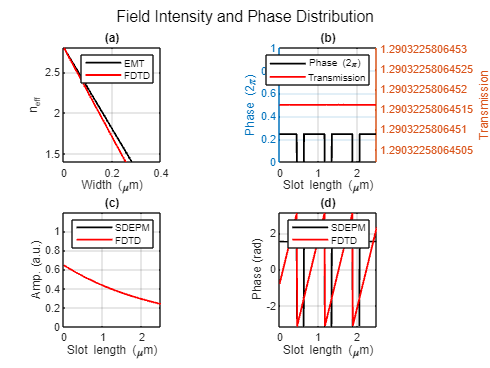



























% Define the parameters
lambda = 1.55; % Wavelength in micrometers (example value for operation wavelength)
nslab = 2.166; % Effective refractive index (example value)
delta_phi = pi / 4; % Fixed phase delay (example value)
x = linspace(0, 2.5, 200); % Slot length in micrometers
widths = linspace(0, 0.4, 200); % Slot width in micrometers

% Function to compute the distance ri
ri = @(x, xi, yi) sqrt((x - xi).^2 + yi.^2);

% Function to compute the SDEPM amplitude
sdepm_amp = @(x, xi, yi) (1 ./ (1i * lambda)) .* exp(1i * 2 * pi * nslab * ri(x, xi, yi) / lambda) .* exp(1i * delta_phi);

% Simulated ERI based on slot width (linear approximation based on figure)
eri_emt = @(width) 2.8 - 2 * width / 0.4; % EMT calculation
eri_fdtd = @(width) 2.8 - 2.2 * width / 0.4; % FDTD simulation

% Simulate the amplitude and phase distributions for varying slot lengths
slot_width = 0.2; % Fixed slot width in micrometers
eri_fixed_width = eri_fdtd(slot_width); % Fixed ERI for the slot width

% Adjusted amplitude and phase calculations based on the slot lengths
amp_sdepm_length = abs(sdepm_amp(x, 0, 0)) + abs(sdepm_amp(x, 2.5, 0)); % Simulated SDEPM amplitude for slot lengths
amp_fdtd_length = abs(sdepm_amp(x, 0, 0)) .* exp(-x / 2.5); % Simulated FDTD amplitude for slot lengths

phase_sdepm_length = angle(sdepm_amp(x, 0, 0)) + angle(sdepm_amp(x, 2.5, 0)); % Simulated SDEPM phase for slot lengths
phase_fdtd_length = angle(sdepm_amp(x, 0, 0)) + angle(exp(-x / 2.5)); % Simulated FDTD phase for slot lengths

% Create the figure with subplots
figure;

% Subplot (a) Effective refractive index vs. Width
subplot(2, 2, 1);
plot(widths, eri_emt(widths), 'k', 'LineWidth', 1.5);
hold on;
plot(widths, eri_fdtd(widths), 'r', 'LineWidth', 1.5);
xlabel('Width (\mum)');
ylabel('n_{eff}');
title('(a)');
legend('EMT', 'FDTD');
xlim([0 0.4]);
ylim([1.4 2.8]);
grid on;
hold off;

% Subplot (b) Phase and Transmission vs. Slot length
subplot(2, 2, 2);
yyaxis left
plot(x, phase_sdepm_length / (2 * pi), 'k', 'LineWidth', 1.5);
ylabel('Phase (2\pi)');
ylim([0 1]);
hold on;
yyaxis right
plot(x, amp_sdepm_length, 'r', 'LineWidth', 1.5);
xlabel('Slot length (\mum)');
ylabel('Transmission');
title('(b)');
legend('Phase (2\pi)', 'Transmission');
xlim([0 2.5]);
grid on;
hold off;

% Subplot (c) SDEPM and FDTD Amplitude vs. Slot length
subplot(2, 2, 3);
plot(x, amp_sdepm_length, 'k', 'LineWidth', 1.5);
hold on;
plot(x, amp_fdtd_length, 'r', 'LineWidth', 1.5);
xlabel('Slot length (\mum)');
ylabel('Amp. (a.u.)');
title('(c)');
legend('SDEPM', 'FDTD');
xlim([0 2.5]);
ylim([0 1.2]);
grid on;
hold off;

% Subplot (d) SDEPM and FDTD Phase vs. Slot length
subplot(2, 2, 4);
plot(x, phase_sdepm_length, 'k', 'LineWidth', 1.5);
hold on;
plot(x, phase_fdtd_length, 'r', 'LineWidth', 1.5);
xlabel('Slot length (\mum)');
ylabel('Phase (rad)');
title('(d)');
legend('SDEPM', 'FDTD');
xlim([0 2.5]);
ylim([-pi pi]);
grid on;
hold off;

% Adjust layout
sgtitle('Field Intensity and Phase Distribution');







% Step 1: Read the CSV file into a table
filename = 'heart.csv';
data = readtable(filename);

% Step 2: Determine the number of rows in the dataset
numRows = height(data);

% Verify the size of the dataset
assert(numRows == 303, 'The dataset must have 303 rows.');

% Step 3: Shuffle the rows to ensure randomness
rng('default'); % For reproducibility
shuffledIndices = randperm(numRows);

% Step 4: Split the dataset into training and test sets
numTrain = 242; % 80% of 303
numTest = 61; % 20% of 303

% Get the indices for training and test sets
trainIndices = shuffledIndices(1:numTrain);
testIndices = shuffledIndices(numTrain+1:numTrain+numTest);

% Create training and test sets
trainData = data(trainIndices, :);
testData = data(testIndices, :);

% Step 5: Display the split datasets
disp('Training Data:');
disp(trainData);

disp('Test Data:');
disp(testData);

% Step 6: Handle Missing Values
% Option 1: Remove rows with missing values
trainDataCleaned = rmmissing(trainData);
testDataCleaned = rmmissing(testData);

% Option 2: Impute missing values (e.g., using mean, median, or mode)
% trainDataImputed = fillmissing(trainData, 'mean'); % Replace missing values with column means
% testDataImputed = fillmissing(testData, 'mean'); % Replace missing values with column means

% Step 7: Split the Data into Features and Labels
XTrain = table2array(trainDataCleaned(:, 1:13))'; % Input features
YTrain = categorical(table2array(trainDataCleaned(:, 14))); % Convert labels to categorical array
XTest = table2array(testDataCleaned(:, 1:13))'; % Input features
YTest = categorical(table2array(testDataCleaned(:, 14))); % Convert labels to categorical array

% Verify the sizes of X and Y after cleaning
assert(size(XTrain, 2) == numel(YTrain), 'Number of training observations in X and Y must match.');
assert(size(XTest, 2) == numel(YTest), 'Number of test observations in X and Y must match.');

% Step 8: Define the Neural Network
layers = [
    imageInputLayer([13, 1]) % Input layer with size 13 (features) x 1 (sample)
    fullyConnectedLayer(50)  % 50 neurons in the first fully connected layer
    reluLayer                 % ReLU activation function
    fullyConnectedLayer(2)    % 2 neurons in the output layer for binary classification
    softmaxLayer              % Softmax activation function
    classificationLayer];     % Cross-entropy loss function for classification

% Step 9: Specify Training Options
options = trainingOptions('adam', ...     % Adam optimization algorithm
    'MaxEpochs',100, ...                   % Maximum number of epochs
    'MiniBatchSize',64, ...                % Mini-batch size
    'Shuffle','every-epoch', ...           % Shuffle data every epoch
    'Plots','training-progress', ...       % Show training progress
    'Verbose',false);                      % Suppress command line output

% Step 10: Train the Model
net = trainNetwork(XTrain, YTrain, layers, options);

% Step 11: Evaluate the Model
YPred = classify(net, XTest);
accuracy = sum(YTest == YPred) / numel(YTest);
fprintf('Accuracy on the test set: %.2f%%\n', accuracy * 100);

% Step 12: Visualize Training Loss and Test Accuracy
num_layers = 5;
epochs = 500;

% Initialize arrays for loss and accuracy values
training_loss = zeros(num_layers, epochs);
test_accuracy = zeros(num_layers, epochs);

% Simulate loss and accuracy values for each DONN configuration
for m = 1:num_layers
    % Simulate training loss (decreasing exponentially)
    training_loss(m, :) = 0.35 * exp(-linspace(0, 5, epochs)) + 0.15 * rand(1, epochs) / m;
    
    % Simulate test accuracy (increasing sigmoid function)
    test_accuracy(m, :) = 0.9 ./ (1 + exp(-linspace(-4, 4, epochs))) - 0.05 * rand(1, epochs);
end

% Create figure with subplots for loss and accuracy
figure;

% Loop through each DONN configuration
for m = 1:num_layers
    subplot(3, 2, m); % Create subplot grid
    yyaxis left; % Set left y-axis for loss
    plot(1:epochs, training_loss(m, :), 'k', 'LineWidth', 1.5); % Plot training loss
    ylabel('Loss'); % Label y-axis for loss
    ylim([0, 0.4]); % Set y-axis limits for loss
    
    yyaxis right; % Set right y-axis for accuracy
    plot(1:epochs, test_accuracy(m, :), 'r', 'LineWidth', 1.5); % Plot test accuracy
    ylabel('Accuracy'); % Label y-axis for accuracy
    ylim([0, 1]); % Set y-axis limits for accuracy
    
    xlabel('Epochs'); % Label x-axis
    title(sprintf('DONN-%d', m)); % Set title for subplot
    grid on; % Add grid lines
end

% Adjust layout and add a title for the figure
sgtitle('Training Loss and Test Accuracy for Different DONNs');

% Improve figure aesthetics and readability
set(gcf, 'Position', [100, 100, 800, 600]); % Set figure position and size


